clc
theta_2 = [40 ,45, 50, 55, 60]

theta_2 =     40    45    50    55    60


theta4 = [70, 76, 83, 91, 100]

theta4 =     70    76    83    91   100


ci = cosd(theta_2)

ci =     0.7660    0.7071    0.6428    0.5736    0.5000


co = cosd(theta4)

co =     0.3420    0.2419    0.1219   -0.0175   -0.1736


diff = cosd(theta_2 - theta4)

diff =     0.8660    0.8572    0.8387    0.8090    0.7660


ci2 = cosd(theta_2).^2

ci2 =     0.5868    0.5000    0.4132    0.3290    0.2500


co2 = cosd(theta4).^2

co2 =     0.1170    0.0585    0.0149    0.0003    0.0302


e1 = [sum(co2), -sum(ci.*co), sum(co);
      sum(co.*ci), -sum(ci2), sum(ci);
      sum(co), -sum(ci), length(theta_2)];
e2 = [sum(co.*diff); sum(ci.*diff); sum(diff)]

e2 =     0.4586
    2.6557
    4.1369


ratios = linsolve(e1,e2)

ratios =     1.0201
    1.6053
    1.7464


%disp(ratios)

K1 = ratios(1)

K1 = 1.0201

%K1 = -0.3085
%K2 = 0.1987
%K3 = 0.9859
K2 = ratios(2)

K2 = 1.6053

K3 = ratios(3)

K3 = 1.7464


fprintf('K1 = %.15g\n',K1)

K1 = 1.02006046121965


fprintf('K2 = %.15g\n',K2)

K2 = 1.60526304463148


fprintf('K3 = %.15g\n',K3)

K3 = 1.74637991389241



fixed = 180

fixed = 180


crank_length = fixed /K1

crank_length = 176.4601

follower_length = fixed / K2

follower_length = 112.1312

coupler_length = sqrt((crank_length*crank_length)+(follower_length*follower_length)+(fixed*fixed)-(K3*2*crank_length*follower_length))

coupler_length = 83.6747


fprintf('crank_length = %.15g\n',crank_length)

crank_length = 176.460128436682


fprintf('follower_length = %.15g\n',follower_length)

follower_length = 112.131155452671


fprintf('coupler_length = %.15g\n',coupler_length)

coupler_length = 83.6747188984759



%transmission angles
theta_i = 40:1:60

theta_i =     40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60


transmission_angle = acosd(((coupler_length^2)+(follower_length^2)-(crank_length^2)-(fixed^2)+(2*crank_length*fixed*cosd(theta_i)))/(2*coupler_length*follower_length))

transmission_angle =    75.4945   77.7545   80.0406   82.3550   84.7004   87.0795   89.4953   91.9513   94.4512   96.9996   99.6012  102.2619  104.9882  107.7879  110.6703  113.6464  116.7298  119.9374  123.2905  126.8170  130.5544


disp('TABLE OF ANGULAR INPUT AND TRANSMISSION ANGLES')

TABLE OF ANGULAR INPUT AND TRANSMISSION ANGLES


disp('   input    transmission   ')

   input    transmission   


disp([theta_i',transmission_angle'])

   40.0000   75.4945
   41.0000   77.7545
   42.0000   80.0406
   43.0000   82.3550
   44.0000   84.7004
   45.0000   87.0795
   46.0000   89.4953
   47.0000   91.9513
   48.0000   94.4512
   49.0000   96.9996
   50.0000   99.6012
   51.0000  102.2619
   52.0000  104.9882
   53.0000  107.7879
   54.0000  110.6703
   55.0000  113.6464
   56.0000  116.7298
   57.0000  119.9374
   58.0000  123.2905
   59.0000  126.8170
   60.0000  130.5544



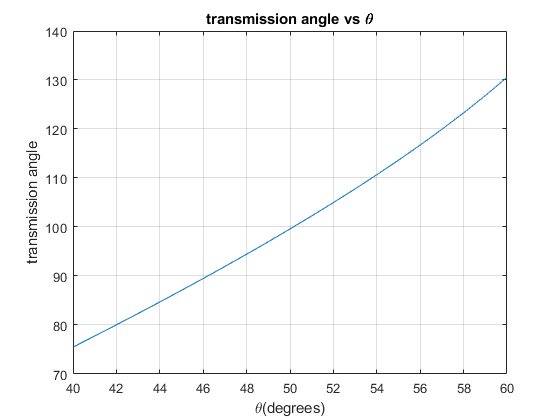

figure(1)
plot(theta_i,transmission_angle),xlabel('\theta(degrees)'),ylabel('transmission angle'),title('transmission angle vs \theta'),grid on


%structural errors
A = sind(theta_i)

A =     0.6428    0.6561    0.6691    0.6820    0.6947    0.7071    0.7193    0.7314    0.7431    0.7547    0.7660    0.7771    0.7880    0.7986    0.8090    0.8192    0.8290    0.8387    0.8480    0.8572    0.8660


B = cosd(theta_i)-K1

B =    -0.2540   -0.2654   -0.2769   -0.2887   -0.3007   -0.3130   -0.3254   -0.3381   -0.3509   -0.3640   -0.3773   -0.3907   -0.4044   -0.4182   -0.4323   -0.4465   -0.4609   -0.4754   -0.4901   -0.5050   -0.5201


C = K3 - K2*cosd(theta_i)

C =     0.5167    0.5349    0.5534    0.5724    0.5917    0.6113    0.6313    0.6516    0.6722    0.6932    0.7145    0.7362    0.7581    0.7803    0.8028    0.8256    0.8487    0.8721    0.8957    0.9196    0.9437



tan_1 = (A + sqrt(A.^2 + B.^2 -C.^2))./(B+C)

tan_1 =     4.1950    4.1535    4.1088    4.0611    4.0106    3.9576    3.9020    3.8442    3.7841    3.7219    3.6576    3.5914    3.5231    3.4529    3.3805    3.3061    3.2294    3.1502    3.0683    2.9832    2.8944


%disp(tan_1)
tan_2 = (A - sqrt(A.^2 + B.^2 -C.^2))./(B+C)

tan_2 =     0.6994    0.7148    0.7308    0.7475    0.7648    0.7828    0.8016    0.8211    0.8415    0.8628    0.8851    0.9084    0.9329    0.9587    0.9860    1.0148    1.0455    1.0784    1.1137    1.1519    1.1937


%disp(tan_2)

out_1 = 2*atand(tan_1);
out_2 = 2*atand(tan_2);
%disp(out_1)
disp(theta_i)

    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60



disp(out_1)

  Columns 1 through 13

  153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079

  Columns 14 through 21

  147.6963  147.0425  146.3419  145.5890  144.7769  143.8965  142.9362  141.8800



disp(out_2)

  Columns 1 through 13

   69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250

  Columns 14 through 21

   87.5858   89.1906   90.8439   92.5509   94.3188   96.1562   98.0750  100.0908



disp(K1)

    1.0201



disp(K2)

    1.6053



disp(K3)

    1.7464




fprintf('We use the second set out_2 as it corresponds with the input output values given in the question')

We use the second set out_2 as it corresponds with the input output values given in the question

structural_error = K1*cosd(out_2)- K2*cosd(theta_i)+ K3 -cosd(theta_i - out_2);
disp(structural_error)

   1.0e-15 *

  Columns 1 through 13

         0   -0.1110    0.1110   -0.1110   -0.1110    0.1110    0.1110         0         0         0         0   -0.1110   -0.2220

  Columns 14 through 21

   -0.1110         0    0.1110   -0.2220    0.1110   -0.1110    0.1110    0.1110



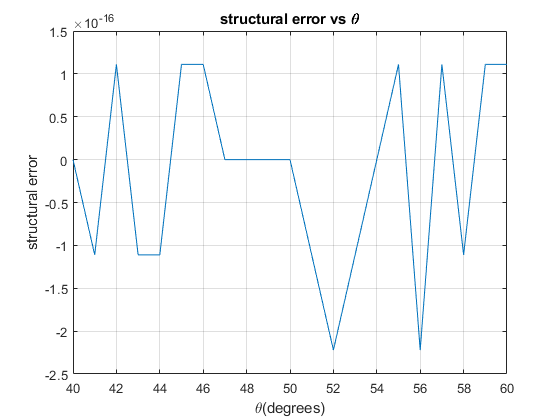

%disp('TABLE OF INPUT ANGLES AND STRUCTURAL ERRORS ')
%disp('   input      error   ')
%disp([theta_i',structural_error'])
figure(2)
plot(theta_i,structural_error),xlabel('\theta(degrees)'),ylabel('structural error'),title('structural error vs \theta'),grid on